# Honours Live Script 5

## Load and Save Data

if ~exist("workspaceVarHonours", 'var')
    load matlabHonours.mat
    setInterpLatex()
end

if exist("workspaceVarHonours", 'var')
    clearVarsArray = clearVars();
    clear(clearVarsArray{:})
    clear clearVarsArray
    save matlabHonours.mat
end 

% set the default intepreter to latex
setInterpLatex()

## Contents

Extracting GBR Subset - Swains

Coral Trout Simulations - Swains

Analysing Results - Swains

## Assumptions Made

% note that specStructCT is set in the previous live script, and contains
% the parameters from Bode et al. 2012 surrogates

% FUCK - need to switch the fecundVec in the specStruct so that the first
% two age classes can't reproduce

## Extracting GBR Subset - Swains

% need to extract the subset of reefs which we are going to use for this
% experiment

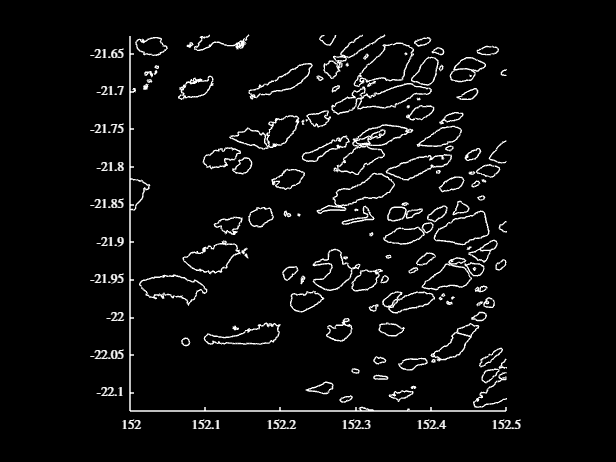

% visualise the area around the Swains
spaceLims = [152, 152.5, -22.125, -21.625];
figure
plotShapeStruct(GBRShapeLL, 'k', [], [], [], spaceLims)
darkFig()

% now, I'll figure out the tolerance which I can use to extract the reefs I
% want
swainsReefsCT = ((centroidsCT(:, 1) < spaceLims(2)) .* ...
    (centroidsCT(:, 1) > spaceLims(1)) .* (centroidsCT(:, 2) > spaceLims(3)) ...
    .* (centroidsCT(:, 2) < spaceLims(4)) .* areasCT > 0.0002) > 0;
nReefsCTSwains = sum(swainsReefsCT)

nReefsCTSwains = 44

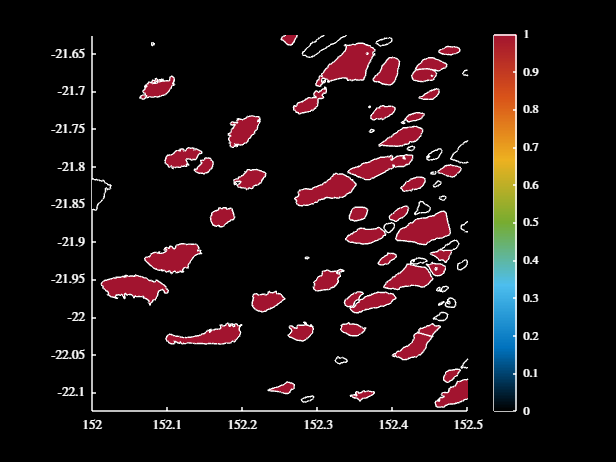


% those look good, so let's grab out the connectivity matrices and other
% things that I need
conMatsCTSwains = conMatsCT;
for m = 1:nMatsCT
    conMatsCTSwains{m} = conMatsCT{m}(swainsReefsCT, swainsReefsCT);
end
areasCTSwains = areasCT(swainsReefsCT);
GBRShapeCTSwains = GBRShapeCT(swainsReefsCT);
centroidsCTSwains = centroidsCT(swainsReefsCT, :);

% visualise the selection
figure
plotShapeStruct(GBRShapeCT, 'k', swainsReefsCT, "fill", [], spaceLims)
darkFig()

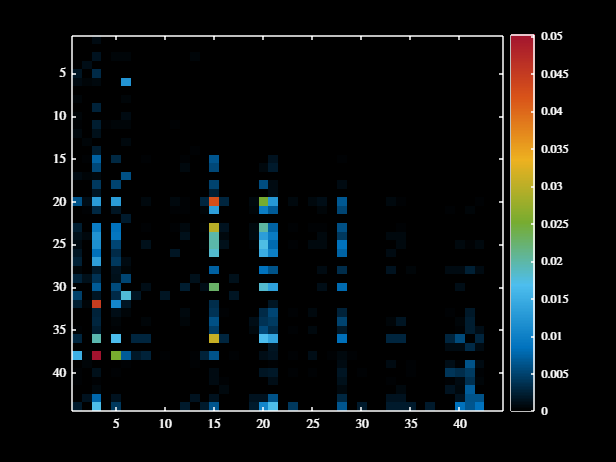

% out of interest, let's plot a couple
% note that these connectivity matrices quite clearly differ significantly
% from most connectivity matrices, in that there is little self
% recruitment, and certain reefs appear to be large sinks
m = 5;
figure
var1 = conMatsCTSwains{m};
imagesc(var1)
colormap(myColourMap())
colorbar
darkFig()

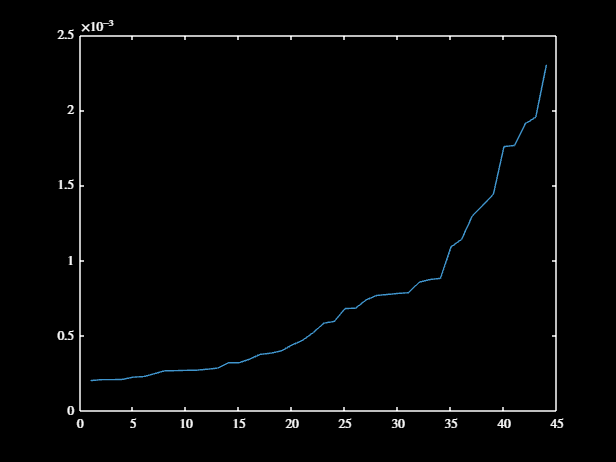

figure
plot(sort(areasCTSwains))
darkFig()

## Coral Trout Simulations - Swains

% run the simulation for a long enough period of time so that the
% populations will stabilise
tWarmup = 1000;
randStruct.randType = "sequence";
randStruct.sequence = randi(length(conMatsCTSwains), 1, tWarmup - 1);
popInitTest = repmat(areasCTSwains, [1, 14]);
popMatTest = baseMetapopModel(conMatsCTSwains, areasCTSwains, ...
        popInitTest, tWarmup, specStructCT, randStruct);

% I'm just going to set the initial populations for each reef in the
% simulations below as the mean of the last 100 years
popInitCTSwains = mean(popMatTest(:, :, (end - 100):end), 3);

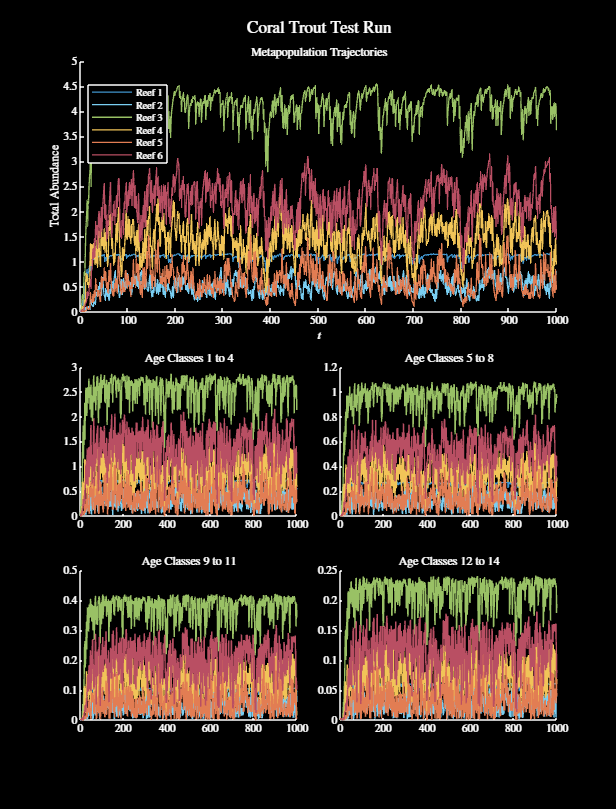

% visualise a random selection of the reefs
var1 = [1, 4, 5, 7, 30, 40];
tL = visualiseMetapop(popMatTest(var1, :, :), 1:tWarmup);
title(tL, "Coral Trout Test Run", 'Interpreter', 'Latex')
darkFig(tL)
figResize(1.75)

% saveCoolFig("coralTroutRun3", "labelsLegend")

clear popMatTest popInitTest

% load in the relevant data
if ~exist("workspaceVarHonours", 'var')
    load matlabHonours.mat
    setInterpLatex()
end

% run the simulations :), this time just forming the portfolios first, and
% doing the rest in a separate loop
nRepsCTSwains = 100;
tWarmup = 100;
tObs = 20;
tFinal = 50;
randStruct = struct();
randStruct.randType = "sequence";
actionStruct.type = "MPA";
actionStruct.actionEffect = successVecCTMPA;
portPerfCTSwains = zeros(nRepsCT, 7);
portVarCTSwains = zeros(size(portPerfCTSwains));
portPerfCTSwainsRetro = zeros(nRepsCT, 7);
portVarCTSwainsRetro = zeros(size(portPerfCTSwainsRetro));

% because I'm a genius, I'm gonna store the MPAs created at each rep AND
% the random connectivity matrix sequences at each rep - that way I can
% reliably recreate the population trajectories without re - running
% everything
mpaSelCTSwains = cell(nRepsCT, 1);
randSeqCTSwains = cell(nRepsCT, 3);

% also, the costs will be the areas, and the resources will be 30% of the
% entire area
resourcesCTSwains = 0.3 * sum(areasCTSwains);

% time stuff
tic

% loop over each run and construct the portfolios only
for r = 1:nRepsCT

    % run the metapopulation model for the warmup period
    randStruct.sequence = randi(nMatsCT, 1, tWarmup - 1);
    randSeqCTSwains{r, 1} = randStruct.sequence;
    popMatWarmup = baseMetapopModel(conMatsCTSwains, areasCTSwains, ...
        popInitCTSwains, tWarmup, specStructCT, randStruct);

    % run the metapopulation model for the observational period
    randStruct.sequence = randi(nMatsCT, 1, tObs - 1);
    randSeqCTSwains{r, 2} = randStruct.sequence;
    popMatObs = baseMetapopModel(conMatsCTSwains, areasCTSwains, ...
        squeeze(popMatWarmup(:, :, end)), tObs, specStructCT, ...
        randStruct);

    % convert the age structured population trajectories into a single,
    % size class weighted sum
    biomassMat = convertAgeClasses(popMatObs, massVecCT);

    % calculate the MPA networks
    boundVals = zeros(2, 2);
    mpaSelCTSwains{r} = cell(1, 7);
    [mpaSelCTSwains{r}{1}, boundVals(1, 2), boundVals(2, 2)] = applyMPT( ...
        biomassMat, 1, "discrete", resourcesCTSwains, areasCTSwains);
    [mpaSelCTSwains{r}{5}, boundVals(1, 1), boundVals(2, 1)] = applyMPT( ...
        biomassMat, 0, "discrete", resourcesCTSwains, areasCTSwains);
    mpaSelCTSwains{r}{2} = applyMPT(biomassMat, 0.75, "discrete", ...
        resourcesCTSwains, areasCTSwains, boundVals);
    mpaSelCTSwains{r}{3} = applyMPT(biomassMat, 0.5, "discrete", ...
        resourcesCTSwains, areasCTSwains, boundVals);
    mpaSelCTSwains{r}{4} = applyMPT(biomassMat, 0.25, "discrete", ...
        resourcesCTSwains, areasCTSwains, boundVals);

    % form the random portfolio, and the zero portfolio
    reefSeq = randperm(nReefsCTSwains);
    mpaSelCTSwains{r}{6} = zeros(1, nReefsCTSwains);
    for i = 1:nReefsCTSwains
        randPortTemp = mpaSelCTSwains{r}{6};
        randPortTemp(reefSeq(i)) = 1;
        if randPortTemp * areasCTSwains < resourcesCTSwains
            mpaSelCTSwains{r}{6} = randPortTemp;
        end
    end
    mpaSelCTSwains{r}{7} = zeros(1, nReefsCTSwains);

    % select a sequence of connectivity matrices for the final time period,
    % which will be the same across all portfolio samples
    randStruct.sequence = randi(nMatsCT, 1, tFinal - 1);
    randSeqCTSwains{r, 3} = randStruct.sequence;

    % every 10 iterations print the time and save the results
    if mod(r, 10) == 0
        disp(r)
        toc
        currTime = toc;
        save matlabSwainsExp.mat mpaSelCTSwains randSeqCTSwains
    end

end

% save the results
save matlabSwainsExp.mat mpaSelCTSwains randSeqCTSwains resourcesCTSwains

% clear some of the redundant variables
clear popMatCell popMatWarmup popMatObs

% load in the data from the experiments
load matlabSwainsExp.mat

% loop over each run, and evaluate the portfolios created above
for r = 1:nRepsCT

    % run the metapopulation model for the warmup period
    randStruct.sequence = randSeqCTSwains{r, 1};
    popMatWarmup = baseMetapopModel(conMatsCTSwains, areasCTSwains, ...
        popInitCTSwains, tWarmup, specStructCT, randStruct);

    % run the metapopulation model for the observational period
    randStruct.sequence = randSeqCTSwains{r, 2};
    popMatObs = baseMetapopModel(conMatsCTSwains, areasCTSwains, ...
        squeeze(popMatWarmup(:, :, end)), tObs, specStructCT, ...
        randStruct);

    % test the retroactive performance of the MPAs
    popMatCell = cell(1, length(mpaSelCTSwains{r}));
    for m = 1:length(mpaSelCTSwains{r})
        actionStruct.actionVec = mpaSelCTSwains{r}{m};
        popMatCell{m} = baseMetapopModel(conMatsCTSwains, areasCTSwains, ...
            squeeze(popMatWarmup(:, :, end)), tObs, specStructCT, ...
            randStruct, actionStruct);
    end
    
    % evaluate the retroactive performance of the MPA selections
    for m = 1:length(mpaSelCTSwains{r})
        [portPerfCTSwainsRetro(r, m), perfTimed] = objFuncMPA(popMatCell{m}, ...
            massVecCT);
        portVarCTSwainsRetro(r, m) = var(perfTimed);
    end

    % select a sequence of connectivity matrices for the final time period,
    % which will be the same across all portfolio samples
    randStruct.sequence = randSeqCTSwains{r, 3};

    % run each of the models for the rest of the testing period
    popMatCell = cell(1, length(mpaSelCTSwains{r}));
    for m = 1:length(mpaSelCTSwains{r})
        actionStruct.actionVec = mpaSelCTSwains{r}{m};
        popMatCell{m} = baseMetapopModel(conMatsCTSwains, areasCTSwains, ...
            squeeze(popMatObs(:, :, end)), tFinal, specStructCT, ...
            randStruct, actionStruct);
    end

    % evaluate the performance of each of the MPA selections
    for m = 1:length(mpaSelCTSwains{r})
        [portPerfCTSwains(r, m), perfTimed] = objFuncMPA(popMatCell{m}, ...
            massVecCT);
        portVarCTSwains(r, m) = var(perfTimed);
    end

end

## Analysing Results - Swains

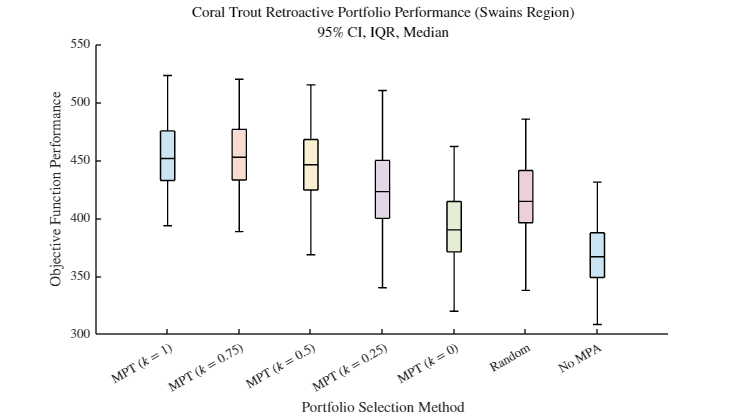

% now, plot the results for the retroactive and future approaches
names = ["MPT ($k = 1$)", "MPT ($k = 0.75$)", "MPT ($k = 0.5$)", ...
    "MPT ($k = 0.25$)", "MPT ($k = 0$)", "Random", "No MPA"];
figure
myBoxPlot(portPerfCTSwainsRetro, names)
xlabel("Portfolio Selection Method")
ylabel("Objective Function Performance")
title("Coral Trout Retroactive Portfolio Performance (Swains Region)")
figRect(0.9, 1.2)
saveFig("CT Portfolio Performance Retroactive (Swains Region)")

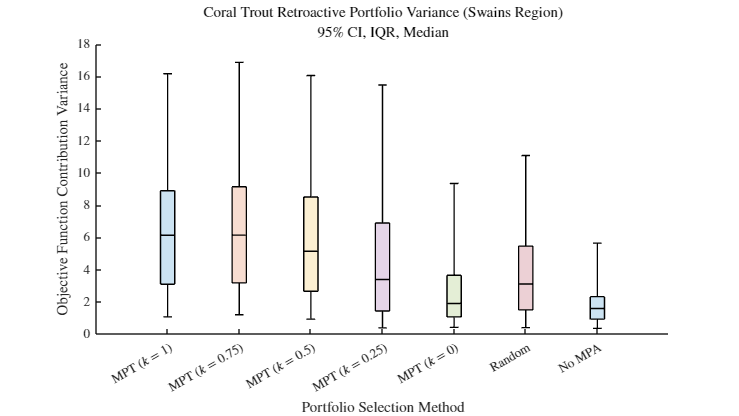

% darkFig()

% look at the variance in yearly objective function contribution
figure
myBoxPlot(portVarCTSwainsRetro, names)
xlabel("Portfolio Selection Method")
ylabel("Objective Function Contribution Variance")
title("Coral Trout Retroactive Portfolio Variance (Swains Region)")
figRect(0.9, 1.2)
saveFig("CT Portfolio Variance Retroactive (Swains Region)")

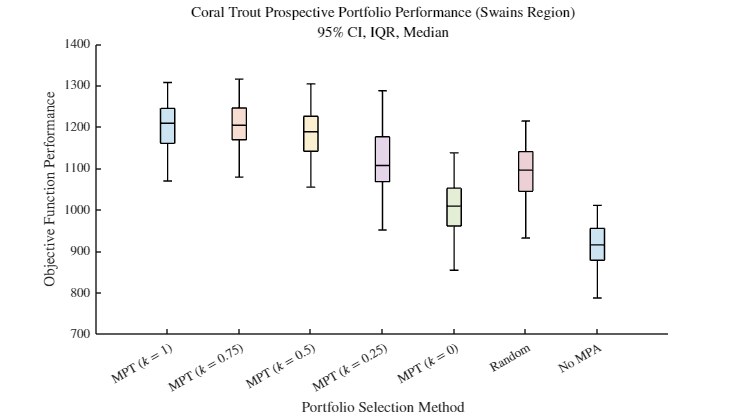


% plot the prospective performance
figure
myBoxPlot(portPerfCTSwains, names)
xlabel("Portfolio Selection Method")
ylabel("Objective Function Performance")
title("Coral Trout Prospective Portfolio Performance (Swains Region)")
figRect(0.9, 1.2)
saveFig("CT Portfolio Performance Prospective (Swains Region)")

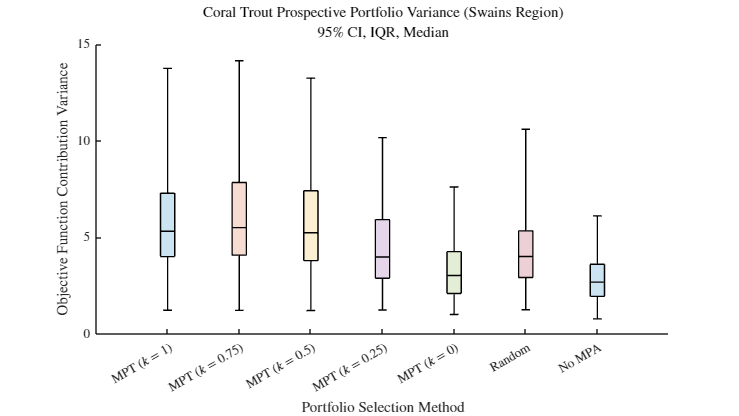


% plot the prospective portfolio variance
figure
myBoxPlot(portVarCTSwains, names)
xlabel("Portfolio Selection Method")
ylabel("Objective Function Contribution Variance")
title("Coral Trout Prospective Portfolio Variance (Swains Region)")
figRect(0.9, 1.2)
saveFig("CT Portfolio Variance Prospective (Swains Region)")

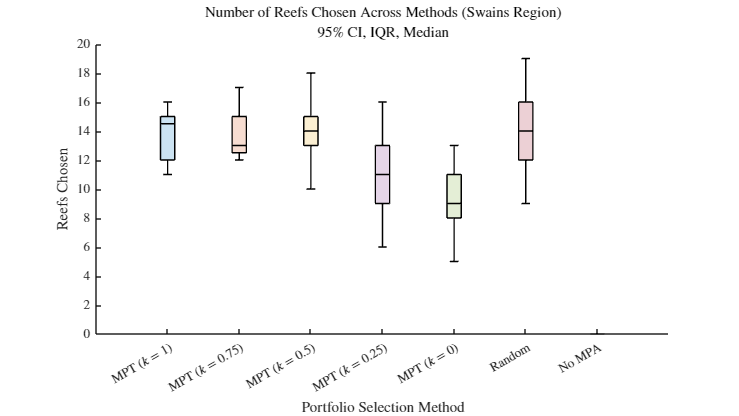


% make a boxplot of the number of reefs chosen
numReefsChosen = zeros(size(portPerfCTSwainsRetro));
for m = 1:size(portPerfCTSwainsRetro, 2)
    for r = 1:size(portPerfCTSwainsRetro, 1)
        numReefsChosen(r, m) = sum(mpaSelCTSwains{r}{m});
    end
end
figure
myBoxPlot(numReefsChosen, names)
xlabel("Portfolio Selection Method")
ylabel("Reefs Chosen")
title("Number of Reefs Chosen Across Methods (Swains Region)")
figRect(0.9, 1.2)
saveFig("CT Number Reefs Chosen (Swains Region)")

% darkFig()

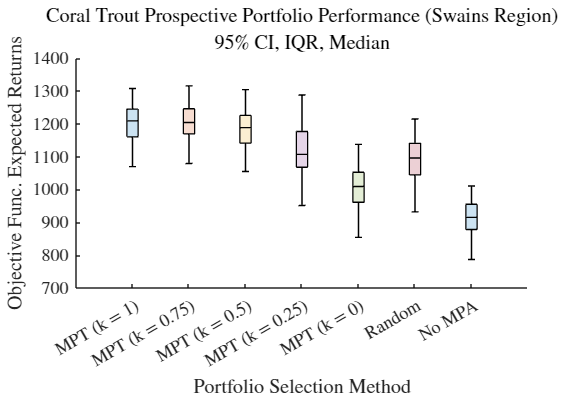

% make some figures for the presentation
fSize = 18;

% plot the prospective performance
figure
myBoxPlot(portPerfCTSwains, names)
xlabel("Portfolio Selection Method", 'FontSize', fSize)
ylabel("Objective Func. Expected Returns", 'FontSize', fSize)
title("Coral Trout Prospective Portfolio Performance (Swains Region)", ...
    'FontSize', fSize)
a = get(gca,'XTickLabel');
set(gca,'XTickLabel', a, 'fontsize', 0.75 * fSize)
figRect(1, 1.1)
saveFig("CT Portfolio Performance Prospective (Swains Region) Pres")

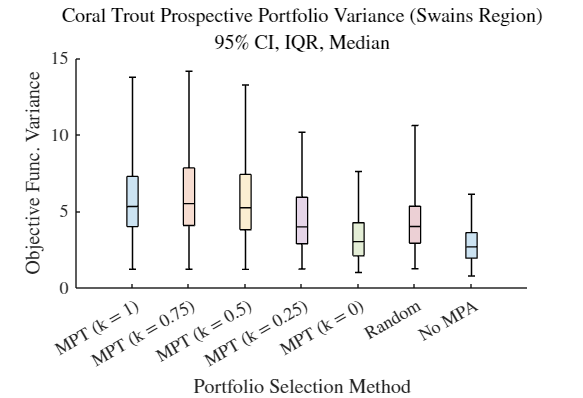


% plot the prospective portfolio variance
figure
myBoxPlot(portVarCTSwains, names)
xlabel("Portfolio Selection Method", 'FontSize', fSize)
ylabel("Objective Func. Variance", 'FontSize', fSize)
title("Coral Trout Prospective Portfolio Variance (Swains Region)", ...
    'FontSize', fSize)
a = get(gca,'XTickLabel');
set(gca,'XTickLabel', a, 'fontsize', 0.75 * fSize)
figRect(1, 1.1)
saveFig("CT Portfolio Variance Prospective (Swains Region) Pres")

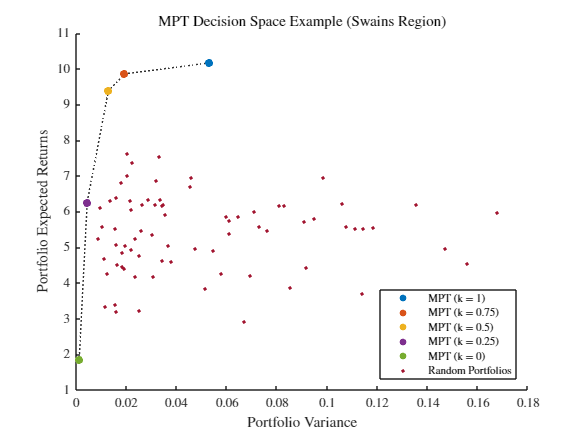

% make the fun little plot of the portfolios for a single example
r = 1;
[portPerfMPT, portPerfRand] = mptVisSimulation(conMatsCTSwains, ...
    areasCTSwains, popInitCTSwains, resourcesCTSwains, randSeqCTSwains, ...
    mpaSelCTSwains, specStructCT, actionStruct.actionEffect, r);

% plot the performance of the selected reefs only, before the MPAs are
% simulated
figure
visualiseMPT(portPerfMPT{1, 1}, portPerfMPT{1, 2}, names, ...
    portPerfRand{1, 1}, portPerfRand{1, 2}, "rand")
title("MPT Decision Space Example (Swains Region)")
hLegend = findobj(gcf, 'Type', 'Legend');
hLegend.Location = 'southeast';
saveFig("MPT Decision Space Example (Swains Region)")

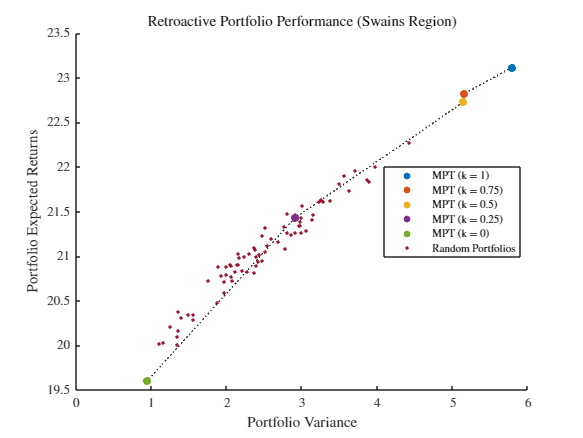


% plot the results for the actual performances on historical connectivity
% matrices
figure
visualiseMPT(portPerfMPT{2, 1}, portPerfMPT{2, 2}, names, ...
    portPerfRand{2, 1}, portPerfRand{2, 2}, "rand")
title("Retroactive Portfolio Performance (Swains Region)")
saveFig("Retroactive Portfolio Performance (Swains Region)")

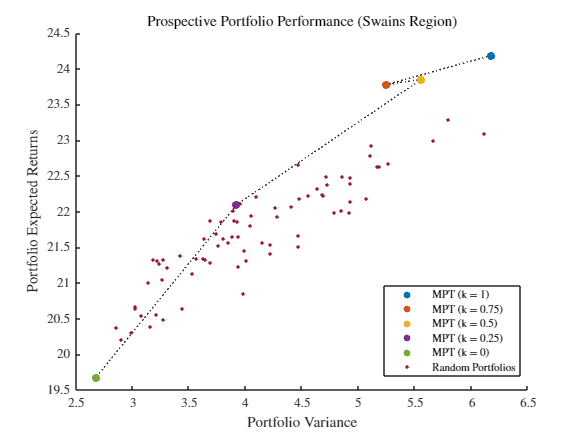


% plot the performance on future connectivity matrices
figure
visualiseMPT(portPerfMPT{3, 1}, portPerfMPT{3, 2}, names, ...
    portPerfRand{3, 1}, portPerfRand{3, 2}, "rand")
title("Prospective Portfolio Performance (Swains Region)")
saveFig("Prospective Portfolio Performance (Swains Region)")

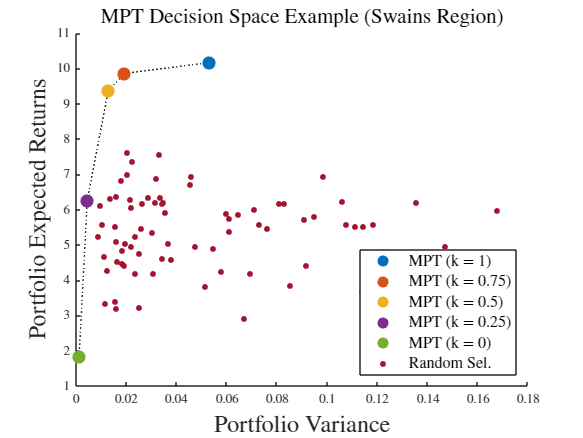

% make a couple plots for the presentation
names2 = names;
names2(end - 1) = "Random Sel.";
names2(end) = "Random Sel.";
figure
visualiseMPT(portPerfMPT{1, 1}, portPerfMPT{1, 2}, names2, ...
    portPerfRand{1, 1}, portPerfRand{1, 2}, "rand", "pres")
title("MPT Decision Space Example (Swains Region)", ...
    'FontSize', 16)
hLegend = findobj(gcf, 'Type', 'Legend');
hLegend.Location = 'southeast';
saveFig("MPT Decision Space Example (Swains Region) Pres")

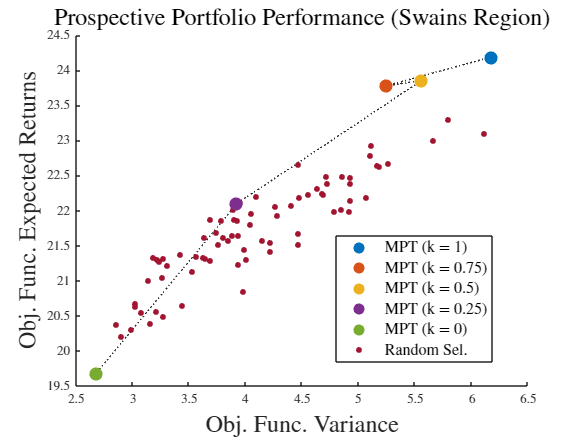


% plot the performance on future connectivity matrices
figure
visualiseMPT(portPerfMPT{3, 1}, portPerfMPT{3, 2}, names2, ...
    portPerfRand{3, 1}, portPerfRand{3, 2}, "rand", "pres")
xlabel("Obj. Func. Variance", "FontSize", 1.65 * 11)
ylabel("Obj. Func. Expected Returns", "FontSize", 1.65 * 11)
title("Prospective Portfolio Performance (Swains Region)", ...
    'FontSize', 18)
saveFig("Prospective Portfolio Performance (Swains Region) Pres")

## Extracting GBR Subset - Townsville

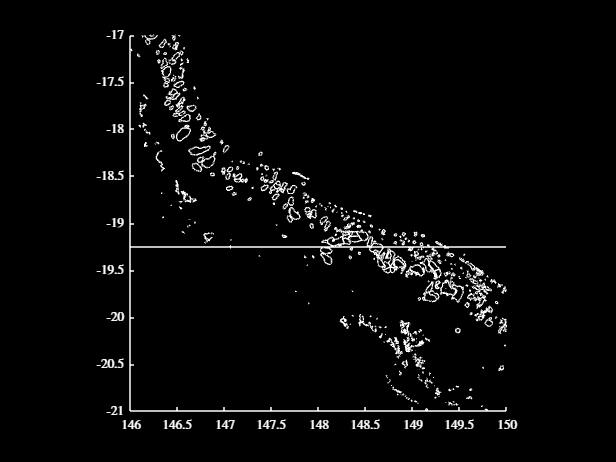

% need to extract the subset of reefs which we are going to use for this
% experiment - visualise the area around Townsville, which itself is at
% about -19 lat
spaceLims = [146, 150, -21, -17];
figure
plotShapeStruct(GBRShapeLL, 'k', [], [], [], spaceLims)
yline(-19.25)
% saveFig("GBRVis")
darkFig()

% now, I'll figure out the tolerance which I can use to extract the reefs I
% want
spaceLims = [147.25, 149.5, -20, -18.5];
townsReefsCT = ((centroidsCT(:, 1) < spaceLims(2)) .* ...
    (centroidsCT(:, 1) > spaceLims(1)) .* (centroidsCT(:, 2) > spaceLims(3)) ...
    .* (centroidsCT(:, 2) < spaceLims(4)) .* areasCT > 0.0007  ) > 0;
nReefsCTTowns = sum(townsReefsCT)

nReefsCTTowns = 47

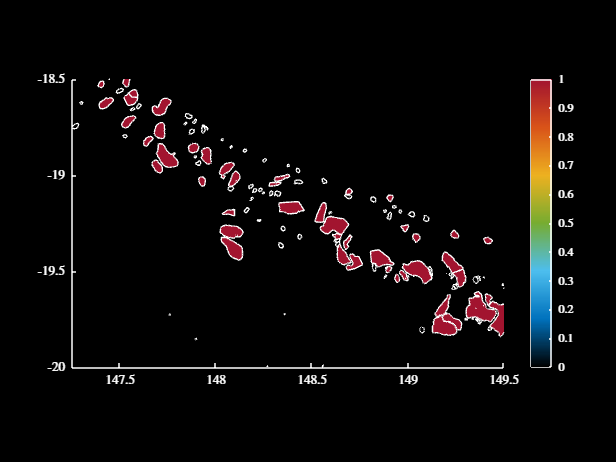


% those look good, so let's grab out the connectivity matrices and other
% things that I need
conMatsCTTowns = conMatsCT;
for m = 1:nMatsCT
    conMatsCTTowns{m} = conMatsCT{m}(townsReefsCT, townsReefsCT);
end
areasCTTowns = areasCT(townsReefsCT);
GBRShapeCTTowns = GBRShapeCT(townsReefsCT);
centroidsCTTowns = centroidsCT(townsReefsCT, :);

% visualise the selection
figure
plotShapeStruct(GBRShapeCT, 'k', townsReefsCT, "fill", [], spaceLims)
darkFig()

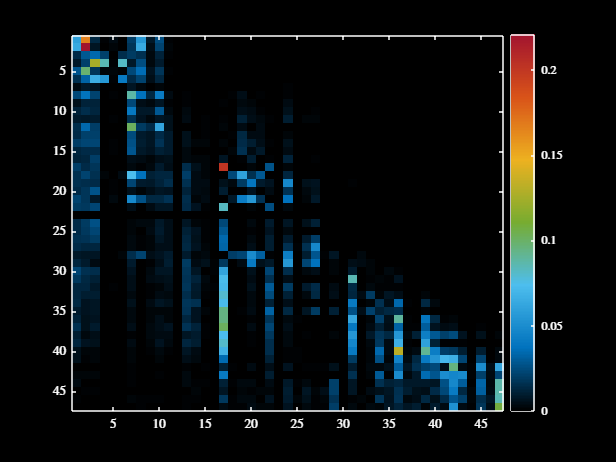

% out of interest, let's plot a couple
% note that these connectivity matrices quite clearly differ significantly
% from most connectivity matrices, in that there is little self
% recruitment, and certain reefs appear to be large sinks
m = 7;
figure
var1 = conMatsCTTowns{m};
imagesc(var1)
colormap(myColourMap())
colorbar
darkFig()

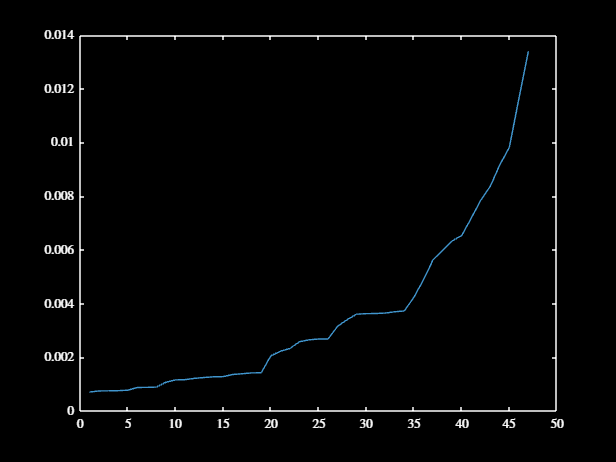

figure
plot(sort(areasCTTowns))
darkFig()

## Coral Trout Simulations - Townsville

% run the simulation for a long enough period of time so that the
% populations will stabilise
tWarmup = 1000;
randStruct.randType = "sequence";
randStruct.sequence = randi(length(conMatsCTTowns), 1, tWarmup - 1);
popInitTest = repmat(areasCTTowns, [1, 14]);
popMatTest = baseMetapopModel(conMatsCTTowns, areasCTTowns, ...
        popInitTest, tWarmup, specStructCT, randStruct);

% I'm just going to set the initial populations for each reef in the
% simulations below as the mean of the last 100 years
popInitCTTowns = mean(popMatTest(:, :, (end - 100):end), 3);

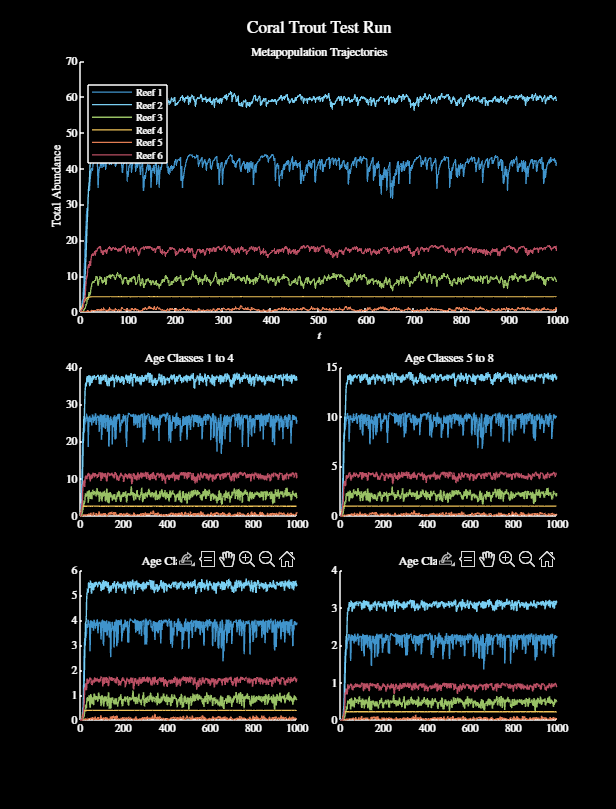

% visualise a random selection of the reefs
var1 = [1, 4, 5, 7, 30, 40];
tL = visualiseMetapop(popMatTest(var1, :, :), 1:tWarmup);
title(tL, "Coral Trout Test Run", 'Interpreter', 'Latex')
darkFig(tL)
figResize(1.75)

% saveCoolFig("coralTroutRun3", "labelsLegend")

clear popMatTest popInitTest

% load in the relevant data
if ~exist("workspaceVarHonours", 'var')
    load matlabHonours.mat
    setInterpLatex()
end

% run the simulations :), this time just forming the portfolios first, and
% doing the rest in a separate loop
nRepsCTTowns = 100;
tWarmup = 100;
tObs = 20;
tFinal = 50;
randStruct = struct();
randStruct.randType = "sequence";
actionStruct.type = "MPA";
actionStruct.actionEffect = successVecCTMPA;
portPerfCTTowns = zeros(nRepsCT, 7);
portVarCTTowns = zeros(size(portPerfCTTowns));
portPerfCTTownsRetro = zeros(nRepsCT, 7);
portVarCTTownsRetro = zeros(size(portPerfCTTownsRetro));

% because I'm a genius, I'm gonna store the MPAs created at each rep AND
% the random connectivity matrix sequences at each rep - that way I can
% reliably recreate the population trajectories without re - running
% everything
mpaSelCTTowns = cell(nRepsCT, 1);
randSeqCTTowns = cell(nRepsCT, 3);

% also, the costs will be the areas, and the resources will be 30% of the
% entire area
resourcesCTTowns = 0.3 * sum(areasCTTowns);

% time stuff
tic

% loop over each run and construct the portfolios only
for r = 1:nRepsCT

    % run the metapopulation model for the warmup period
    randStruct.sequence = randi(nMatsCT, 1, tWarmup - 1);
    randSeqCTTowns{r, 1} = randStruct.sequence;
    popMatWarmup = baseMetapopModel(conMatsCTTowns, areasCTTowns, ...
        popInitCTTowns, tWarmup, specStructCT, randStruct);

    % run the metapopulation model for the observational period
    randStruct.sequence = randi(nMatsCT, 1, tObs - 1);
    randSeqCTTowns{r, 2} = randStruct.sequence;
    popMatObs = baseMetapopModel(conMatsCTTowns, areasCTTowns, ...
        squeeze(popMatWarmup(:, :, end)), tObs, specStructCT, ...
        randStruct);

    % convert the age structured population trajectories into a single,
    % size class weighted sum
    biomassMat = convertAgeClasses(popMatObs, massVecCT);

    % calculate the MPA networks
    boundVals = zeros(2, 2);
    mpaSelCTTowns{r} = cell(1, 7);
    [mpaSelCTTowns{r}{1}, boundVals(1, 2), boundVals(2, 2)] = applyMPT( ...
        biomassMat, 1, "discrete", resourcesCTTowns, areasCTTowns);
    [mpaSelCTTowns{r}{5}, boundVals(1, 1), boundVals(2, 1)] = applyMPT( ...
        biomassMat, 0, "discrete", resourcesCTTowns, areasCTTowns);
    mpaSelCTTowns{r}{2} = applyMPT(biomassMat, 0.75, "discrete", ...
        resourcesCTTowns, areasCTTowns, boundVals);
    mpaSelCTTowns{r}{3} = applyMPT(biomassMat, 0.5, "discrete", ...
        resourcesCTTowns, areasCTTowns, boundVals);
    mpaSelCTTowns{r}{4} = applyMPT(biomassMat, 0.25, "discrete", ...
        resourcesCTTowns, areasCTTowns, boundVals);

    % form the random portfolio, and the zero portfolio
    reefSeq = randperm(nReefsCTTowns);
    mpaSelCTTowns{r}{6} = zeros(1, nReefsCTTowns);
    for i = 1:nReefsCTTowns
        randPortTemp = mpaSelCTTowns{r}{6};
        randPortTemp(reefSeq(i)) = 1;
        if randPortTemp * areasCTTowns < resourcesCTTowns
            mpaSelCTTowns{r}{6} = randPortTemp;
        end
    end
    mpaSelCTTowns{r}{7} = zeros(1, nReefsCTTowns);

    % select a sequence of connectivity matrices for the final time period,
    % which will be the same across all portfolio samples
    randStruct.sequence = randi(nMatsCT, 1, tFinal - 1);
    randSeqCTTowns{r, 3} = randStruct.sequence;

    % every 10 iterations print the time and save the results
    if mod(r, 10) == 0
        disp(r)
        toc
        currTime = toc;
        save matlabTownsExp.mat mpaSelCTTowns randSeqCTTowns
    end

end

% save the results
save matlabTownsExp.mat mpaSelCTTowns randSeqCTTowns resourcesCTTowns

% clear some of the redundant variables
clear popMatCell popMatWarmup popMatObs

% load in the data from the experiments
load matlabTownsExp.mat

% loop over each run, and evaluate the portfolios created above
for r = 1:nRepsCT

    % run the metapopulation model for the warmup period
    randStruct.sequence = randSeqCTTowns{r, 1};
    popMatWarmup = baseMetapopModel(conMatsCTTowns, areasCTTowns, ...
        popInitCTTowns, tWarmup, specStructCT, randStruct);

    % run the metapopulation model for the observational period
    randStruct.sequence = randSeqCTTowns{r, 2};
    popMatObs = baseMetapopModel(conMatsCTTowns, areasCTTowns, ...
        squeeze(popMatWarmup(:, :, end)), tObs, specStructCT, ...
        randStruct);

    % test the retroactive performance of the MPAs
    popMatCell = cell(1, length(mpaSelCTTowns{r}));
    for m = 1:length(mpaSelCTTowns{r})
        actionStruct.actionVec = mpaSelCTTowns{r}{m};
        popMatCell{m} = baseMetapopModel(conMatsCTTowns, areasCTTowns, ...
            squeeze(popMatWarmup(:, :, end)), tObs, specStructCT, ...
            randStruct, actionStruct);
    end
    
    % evaluate the retroactive performance of the MPA selections
    for m = 1:length(mpaSelCTTowns{r})
        [portPerfCTTownsRetro(r, m), perfTimed] = objFuncMPA(popMatCell{m}, ...
            massVecCT);
        portVarCTTownsRetro(r, m) = var(perfTimed);
    end

    % select a sequence of connectivity matrices for the final time period,
    % which will be the same across all portfolio samples
    randStruct.sequence = randSeqCTTowns{r, 3};

    % run each of the models for the rest of the testing period
    popMatCell = cell(1, length(mpaSelCTTowns{r}));
    for m = 1:length(mpaSelCTTowns{r})
        actionStruct.actionVec = mpaSelCTTowns{r}{m};
        popMatCell{m} = baseMetapopModel(conMatsCTTowns, areasCTTowns, ...
            squeeze(popMatObs(:, :, end)), tFinal, specStructCT, ...
            randStruct, actionStruct);
    end

    % evaluate the performance of each of the MPA selections
    for m = 1:length(mpaSelCTTowns{r})
        [portPerfCTTowns(r, m), perfTimed] = objFuncMPA(popMatCell{m}, ...
            massVecCT);
        portVarCTTowns(r, m) = var(perfTimed);
    end

end

## Analysing Results - Towns

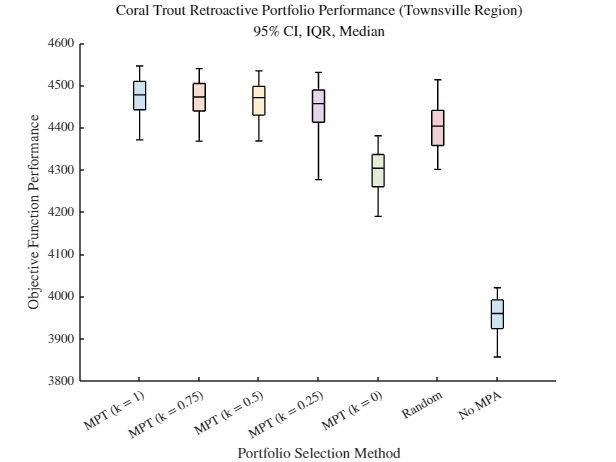

% now, plot the results for the retroactive and future approaches
names = ["MPT (k = 1)", "MPT (k = 0.75)", "MPT (k = 0.5)", ...
    "MPT (k = 0.25)", "MPT (k = 0)", "Random", "No MPA"];
figure
myBoxPlot(portPerfCTTownsRetro, names)
xlabel("Portfolio Selection Method")
ylabel("Objective Function Performance")
title("Coral Trout Retroactive Portfolio Performance (Townsville Region)")
saveFig("CT Portfolio Performance Retroactive (Townsville Region)")

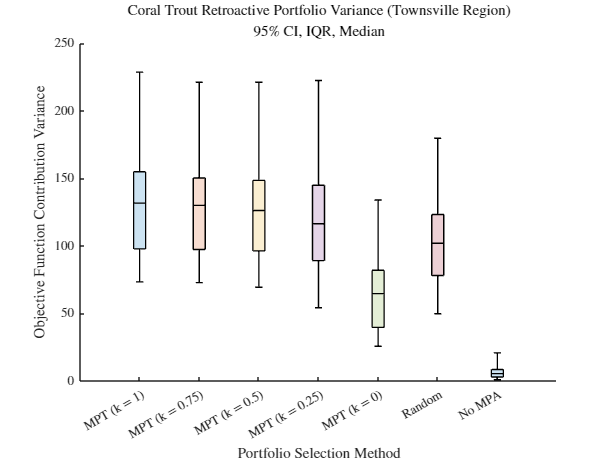


% look at the variance in yearly objective function contribution
figure
myBoxPlot(portVarCTTownsRetro, names)
xlabel("Portfolio Selection Method")
ylabel("Objective Function Contribution Variance")
title("Coral Trout Retroactive Portfolio Variance (Townsville Region)")
saveFig("CT Portfolio Variance Retroactive (Townsville Region)")

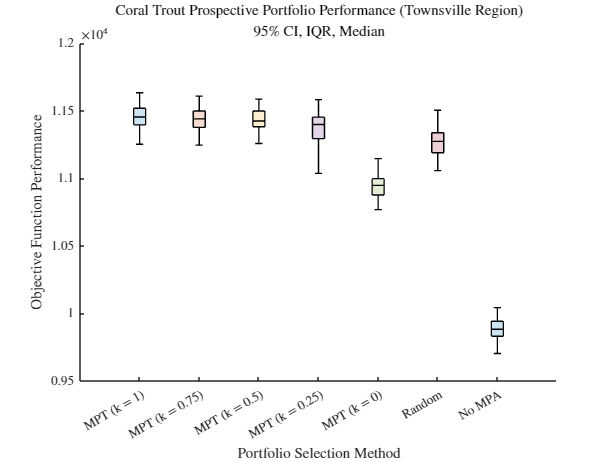


% plot the prospective performance
figure
myBoxPlot(portPerfCTTowns, names)
xlabel("Portfolio Selection Method")
ylabel("Objective Function Performance")
title("Coral Trout Prospective Portfolio Performance (Townsville Region)")
saveFig("CT Portfolio Performance Prospective (Townsville Region)")

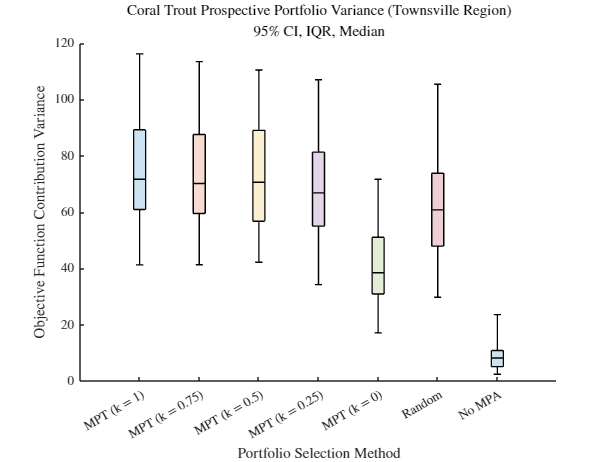


% plot the prospective portfolio variance
figure
myBoxPlot(portVarCTTowns, names)
xlabel("Portfolio Selection Method")
ylabel("Objective Function Contribution Variance")
title("Coral Trout Prospective Portfolio Variance (Townsville Region)")
saveFig("CT Portfolio Variance Prospective (Townsville Region)")

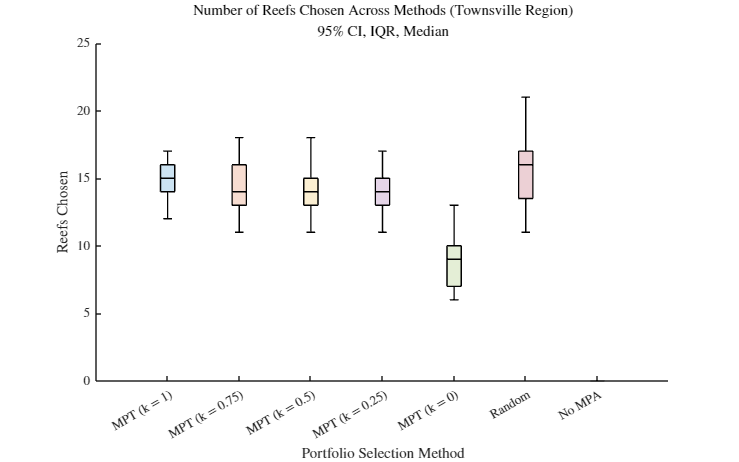


% make a boxplot of the number of reefs chosen
numReefsChosen = zeros(size(portPerfCTTownsRetro));
for m = 1:size(portPerfCTTownsRetro, 2)
    for r = 1:size(portPerfCTTownsRetro, 1)
        numReefsChosen(r, m) = sum(mpaSelCTTowns{r}{m});
    end
end
figure
myBoxPlot(numReefsChosen, names)
xlabel("Portfolio Selection Method")
ylabel("Reefs Chosen")
title("Number of Reefs Chosen Across Methods (Townsville Region)")
figRect(1, 1.2)
saveFig("CT Number Reefs Chosen (Townsville Region)")

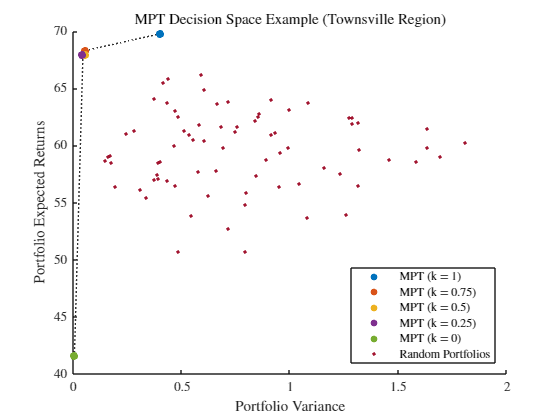

% make the fun little plot of the portfolios for a single example
r = 6;
[portPerfMPT, portPerfRand] = mptVisSimulation(conMatsCTTowns, ...
    areasCTTowns, popInitCTTowns, resourcesCTTowns, randSeqCTTowns, ...
    mpaSelCTTowns, specStructCT, actionStruct.actionEffect, r);

% plot the performance of the selected reefs only, before the MPAs are
% simulated
figure
visualiseMPT(portPerfMPT{1, 1}, portPerfMPT{1, 2}, names, ...
    portPerfRand{1, 1}, portPerfRand{1, 2}, "rand")
title("MPT Decision Space Example (Townsville Region)")
hLegend = findobj(gcf, 'Type', 'Legend');
hLegend.Location = 'southeast';
saveFig("MPT Decision Space Example (Townsville Region)")

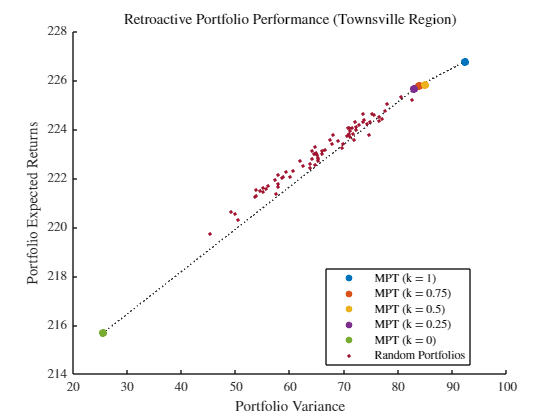


% plot the results for the actual performances on historical connectivity
% matrices
figure
visualiseMPT(portPerfMPT{2, 1}, portPerfMPT{2, 2}, names, ...
    portPerfRand{2, 1}, portPerfRand{2, 2}, "rand")
title("Retroactive Portfolio Performance (Townsville Region)")
saveFig("Retroactive Portfolio Performance (Townsville Region)")

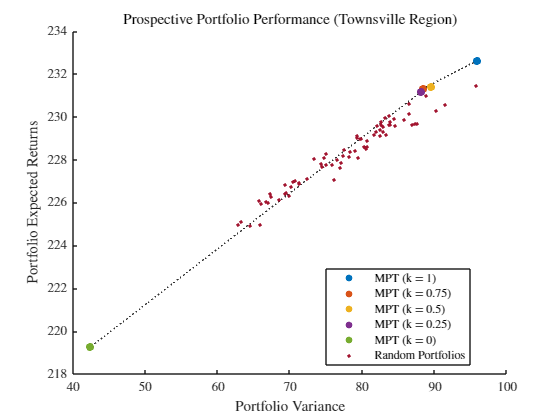


% plot the performance on future connectivity matrices
figure
visualiseMPT(portPerfMPT{3, 1}, portPerfMPT{3, 2}, names, ...
    portPerfRand{3, 1}, portPerfRand{3, 2}, "rand")
title("Prospective Portfolio Performance (Townsville Region)")
saveFig("Prospective Portfolio Performance (Townsville Region)")